# Projeto do dia 23/10/2020

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

**Boas práticas**

clear all;
clc;
close all;

**Dados:**

- 
$$G(s)=\frac{378.8}{s^2+(120\pi)^2}$$


- 
$$T=0.2\pi
$$


**Aproximações:**

- 
$$s=\frac{z-1}{T}$$


- 
$$s=\frac{z-1}{Tz}$$


- 
$$s=\frac{2}{T}\frac{z-1}{z+1}$$


**Perguntas importantes:**

- Resposta impulsiva para as 3 aproximações;

- Os pólos de cada uma das aprox e o respectivo pzmap. Argumentar acerca da estabilidade;

- Verificar se o resultado é o esperado: $f_{osc}$ = 60Hz e amplitude de $\pm$1Vp;

- Verificar o mapeamento s --> z para os 3 casos. Variar o s e verificar o ponto no plano Z;

- Resposta ao degrau. Como se interpreta o resultado?

- Comparar no simulink com a equação de diferenças - Contínuo + discreto + eq. de diferenças;

- Degrau, rampa e senoide.

**Estrutura**

syms z s T;

G = 378.8/(s^2+(120*pi)^2);

sz1 = (z-1)/T;
sz2 = (z-1)/(T*z);
sz3 = (2*(z-1))/(T*(z+1));

% Substitui as formulas de sz, criando um G pra cada equacao
% Tambem ja simplifica a fracao obtida
Gz1 = simplifyFraction(subs(G,s,sz1))

$$Gz1 = \frac{65077344468992\,T^{2}}{5\,\left(4883285160246119\,T^{2}+34359738368\,z^{2}-68719476736\,z+34359738368\right)}$$


Gz2 = simplifyFraction(subs(G,s,sz2))

$$Gz2 = \frac{65077344468992\,T^{2}\,z^{2}}{5\,\left(4883285160246119\,T^{2}\,z^{2}+34359738368\,z^{2}-68719476736\,z+34359738368\right)}$$


Gz3 = simplifyFraction(subs(G,s,sz3))

$$Gz3 = \frac{65077344468992\,T^{2}\,{\left(z+1\right)}^{2}}{5\,\left(4883285160246119\,T^{2}\,z^{2}+9766570320492238\,T^{2}\,z+4883285160246119\,T^{2}+137438953472\,z^{2}-274877906944\,z+137438953472\right)}$$


% Adota valor de T e substitui nos Gzs
T = 0.2*pi

T = 0.6283

Gz1 = eval(Gz1)

$$Gz1 = \frac{6577025488715485}{256\,\left(171798691840\,z^{2}-343597383680\,z+\frac{38557561362238915}{4}\right)}$$

Gz2 = eval(Gz2)

$$Gz2 = \frac{6577025488715485\,z^{2}}{256\,\left(\frac{38557561362238915\,z^{2}}{4}-343597383680\,z+171798691840\right)}$$

Gz3 = eval(Gz3)

$$Gz3 = \frac{6577025488715485\,{\left(z+1\right)}^{2}}{256\,\left(\frac{38559622946540995\,z^{2}}{4}+\frac{38554125388402115\,z}{2}+\frac{38559622946540995}{4}\right)}$$


z = tf('z',T)

z =
 
  z
 
Sample time: 0.62832 seconds
Discrete-time transfer function.




ExpFun = matlabFunction(Gz1);
ExpFun = str2func(regexprep(func2str(ExpFun), '\.([/^\\*])', '$1'));
Gz1 = ExpFun(z)

Gz1 =
 
                2.569e13
  ------------------------------------
  1.718e11 z^2 - 3.436e11 z + 9.639e15
 
Sample time: 0.62832 seconds
Discrete-time transfer function.



figure()
num1 = cell2mat(Gz1.Numerator)

num1 = 	1.0e+13 *

         0         0    2.5692


den1 = cell2mat(Gz1.Denominator)

den1 = 	1.0e+15 *

    0.0002   -0.0003    9.6394


raiz1 = roots(den1)

raiz1 = 	1.0e+02 *

   0.0100 + 2.3687i
   0.0100 - 2.3687i


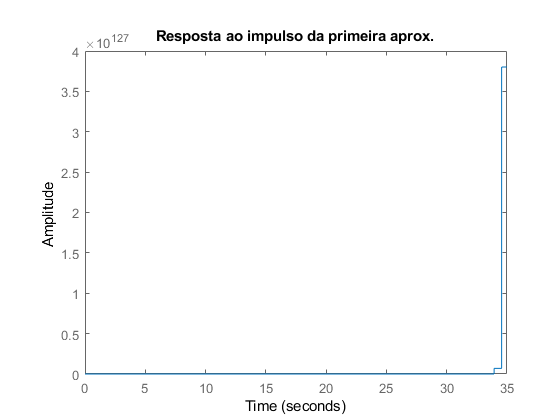

impulse(Gz1)
title('Resposta ao impulso da primeira aprox.')

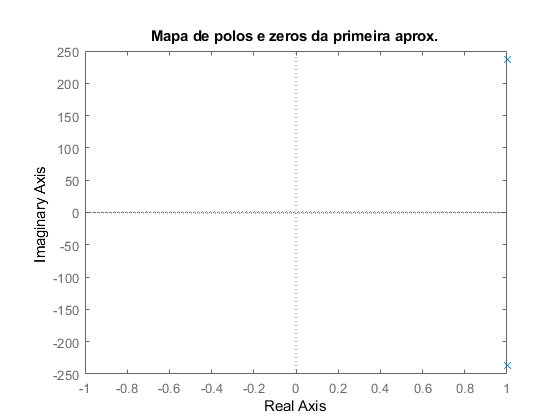

pzmap(Gz1)
title('Mapa de polos e zeros da primeira aprox.')


ExpFun = matlabFunction(Gz2);
ExpFun = str2func(regexprep(func2str(ExpFun), '\.([/^\\*])', '$1'));
Gz2 = ExpFun(z)

Gz2 =
 
              2.569e13 z^2
  ------------------------------------
  9.639e15 z^2 - 3.436e11 z + 1.718e11
 
Sample time: 0.62832 seconds
Discrete-time transfer function.



figure()
num2 = cell2mat(Gz2.Numerator)

num2 = 	1.0e+13 *

    2.5692         0         0


den2 = cell2mat(Gz2.Denominator)

den2 = 	1.0e+15 *

    9.6394   -0.0003    0.0002


raiz2 = roots(den2)

raiz2 =    0.0000 + 0.0042i
   0.0000 - 0.0042i


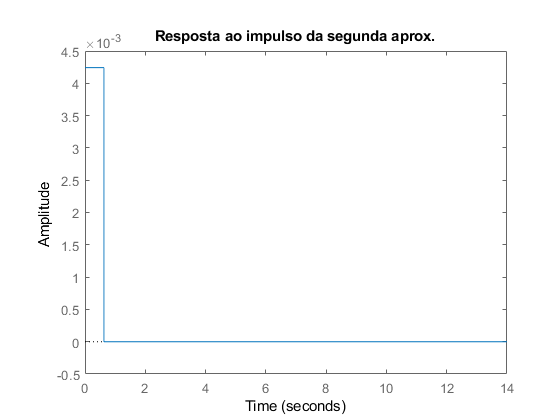

impulse(Gz2)
title('Resposta ao impulso da segunda aprox.')

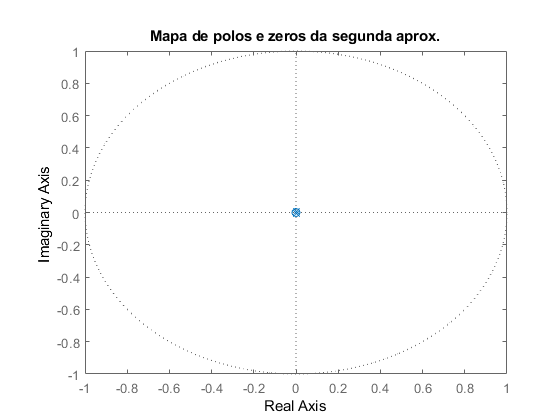

pzmap(Gz2)
title('Mapa de polos e zeros da segunda aprox.')


ExpFun = matlabFunction(Gz3);
ExpFun = str2func(regexprep(func2str(ExpFun), '\.([/^\\*])', '$1'));
Gz3 = ExpFun(z)

Gz3 =
 
  2.569e13 z^2 + 5.138e13 z + 2.569e13
  ------------------------------------
   9.64e15 z^2 + 1.928e16 z + 9.64e15
 
Sample time: 0.62832 seconds
Discrete-time transfer function.



figure()
num3 = cell2mat(Gz3.Numerator)

num3 = 	1.0e+13 *

    2.5692    5.1383    2.5692


den3 = cell2mat(Gz3.Denominator)

den3 = 	1.0e+16 *

    0.9640    1.9277    0.9640


raiz3 = roots(den3)

raiz3 =   -0.9999 + 0.0169i
  -0.9999 - 0.0169i


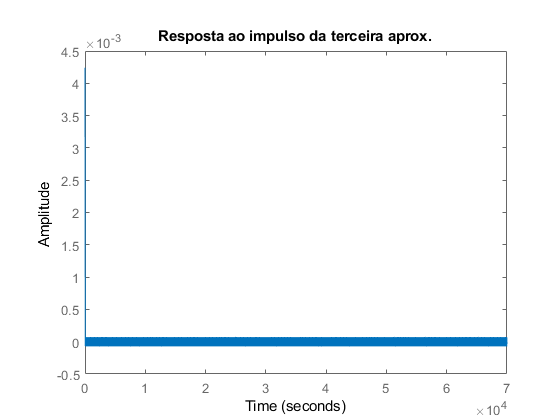

impulse(Gz3)
title('Resposta ao impulso da terceira aprox.')

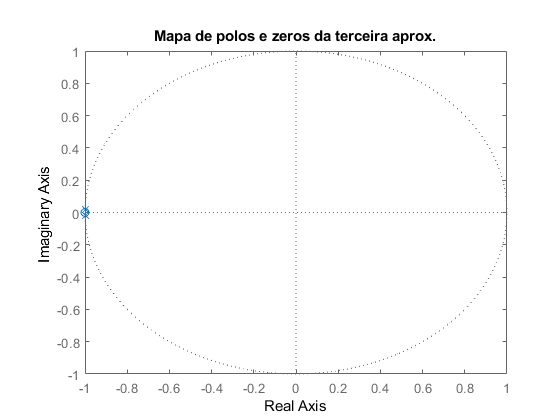

pzmap(Gz3)
title('Mapa de polos e zeros da terceira aprox.')

Nenhuma das respostas à impulsos deu como esperado. O que teoricamente deveria ser mais próximo seria a terceira aprox., mas esta chegou num valor menor que $10^{-4}$ Vp e frequência de alta, próxima de1Hz.

**Mapeamento**

- $s=\frac{z-1}{T}$ (a resposta ao impulso)

                $z=Ts+1
$(I)

          2. $s=\frac{z-1}{Tz}$

                $Tzs = z-1$   --> $z(Ts-1)=-1$  -->

                $z=\frac{-1}{Ts-1}=\frac{1}{1-Ts}$  (II)

          3. $s=\frac{2}{T}\frac{z-1}{z+1}$

                  $s=\frac{2z-2}{Tz+T}$  --> $Tzs + Ts = 2z-2$  --> $z (Ts -2) = -2-Ts$ -->

                  $z=\frac{-2-Ts}{Ts-2}$ (III)

S = valores_S();
Z1 = @(s) T*s + 1 

Z1 = function_handle with value:
    @(s)T*s+1


polos1 = Z1(S)

polos1 =    1.0000 + 0.0000i   0.9372 + 0.0000i   0.8743 + 0.0000i   0.8115 + 0.0000i   0.7487 + 0.0000i   0.6858 + 0.0000i   0.6230 + 0.0000i   0.5602 + 0.0000i   0.4973 + 0.0000i   0.4345 + 0.0000i   0.3717 + 0.0000i   0.3088 + 0.0000i   0.2460 + 0.0000i   0.1832 + 0.0000i   0.1204 + 0.0000i   0.0575 + 0.0000i  -0.0053 + 0.0000i  -0.0681 + 0.0000i  -0.1310 + 0.0000i  -0.1938 + 0.0000i  -0.2566 + 0.0000i  -0.3195 + 0.0000i  -0.3823 + 0.0000i  -0.4451 + 0.0000i  -0.5080 + 0.0000i  -0.5708 + 0.0000i  -0.6336 + 0.0000i  -0.6965 + 0.0000i  -0.7593 + 0.0000i  -0.8221 + 0.0000i  -0.8850 + 0.0000i  -0.9478 + 0.0000i  -1.0106 + 0.0000i  -1.0735 + 0.0000i  -1.1363 + 0.0000i  -1.1991 + 0.0000i  -1.2619 + 0.0000i  -1.3248 + 0.0000i  -1.3876 + 0.0000i  -1.4504 + 0.0000i  -1.5133 + 0.0000i  -1.5761 + 0.0000i  -1.6389 + 0.0000i  -1.7018 + 0.0000i  -1.7646 + 0.0000i  -1.8274 + 0.0000i  -1.8903 + 0.0000i  -1.9531 + 0.0000i  -2.0159 + 0.0000i  -2.0788 + 0.0000i
   1.0000 + 0.0000i   1.0000 - 0.0628i  

Z2 = @(s) 1./(1-T*s)

Z2 = function_handle with value:
    @(s)1./(1-T*s)


polos2 = Z2(S)

polos2 =    1.0000 + 0.0000i   0.9409 + 0.0000i   0.8884 + 0.0000i   0.8414 + 0.0000i   0.7992 + 0.0000i   0.7609 + 0.0000i   0.7262 + 0.0000i   0.6945 + 0.0000i   0.6655 + 0.0000i   0.6388 + 0.0000i   0.6141 + 0.0000i   0.5913 + 0.0000i   0.5701 + 0.0000i   0.5504 + 0.0000i   0.5320 + 0.0000i   0.5148 + 0.0000i   0.4987 + 0.0000i   0.4835 + 0.0000i   0.4693 + 0.0000i   0.4558 + 0.0000i   0.4431 + 0.0000i   0.4311 + 0.0000i   0.4198 + 0.0000i   0.4090 + 0.0000i   0.3987 + 0.0000i   0.3890 + 0.0000i   0.3797 + 0.0000i   0.3709 + 0.0000i   0.3624 + 0.0000i   0.3543 + 0.0000i   0.3466 + 0.0000i   0.3392 + 0.0000i   0.3322 + 0.0000i   0.3254 + 0.0000i   0.3188 + 0.0000i   0.3126 + 0.0000i   0.3066 + 0.0000i   0.3008 + 0.0000i   0.2952 + 0.0000i   0.2898 + 0.0000i   0.2846 + 0.0000i   0.2796 + 0.0000i   0.2748 + 0.0000i   0.2701 + 0.0000i   0.2656 + 0.0000i   0.2613 + 0.0000i   0.2571 + 0.0000i   0.2530 + 0.0000i   0.2490 + 0.0000i   0.2452 + 0.0000i
   1.0000 + 0.0000i   0.9961 - 0.0626i  

Z3 = @(s) (-2-T.*s)./(T.*s-2)

Z3 = function_handle with value:
    @(s)(-2-T.*s)./(T.*s-2)


polos3 = Z3(S)

polos3 =    1.0000 + 0.0000i   0.9391 + 0.0000i   0.8818 + 0.0000i   0.8277 + 0.0000i   0.7767 + 0.0000i   0.7285 + 0.0000i   0.6828 + 0.0000i   0.6395 + 0.0000i   0.5983 + 0.0000i   0.5592 + 0.0000i   0.5219 + 0.0000i   0.4864 + 0.0000i   0.4524 + 0.0000i   0.4200 + 0.0000i   0.3891 + 0.0000i   0.3594 + 0.0000i   0.3310 + 0.0000i   0.3037 + 0.0000i   0.2776 + 0.0000i   0.2524 + 0.0000i   0.2283 + 0.0000i   0.2050 + 0.0000i   0.1826 + 0.0000i   0.1611 + 0.0000i   0.1403 + 0.0000i   0.1202 + 0.0000i   0.1008 + 0.0000i   0.0821 + 0.0000i   0.0640 + 0.0000i   0.0465 + 0.0000i   0.0296 + 0.0000i   0.0132 + 0.0000i  -0.0026 + 0.0000i  -0.0180 + 0.0000i  -0.0329 + 0.0000i  -0.0474 + 0.0000i  -0.0615 + 0.0000i  -0.0751 + 0.0000i  -0.0883 + 0.0000i  -0.1012 + 0.0000i  -0.1137 + 0.0000i  -0.1259 + 0.0000i  -0.1377 + 0.0000i  -0.1493 + 0.0000i  -0.1605 + 0.0000i  -0.1714 + 0.0000i  -0.1820 + 0.0000i  -0.1924 + 0.0000i  -0.2025 + 0.0000i  -0.2124 + 0.0000i
   1.0000 + 0.0000i   0.9980 - 0.0628i  


figure()
plot(polos1,'kX')
title('Mapa de polos e zeros da primeira aprox.')
grid minor
hold

Current plot held


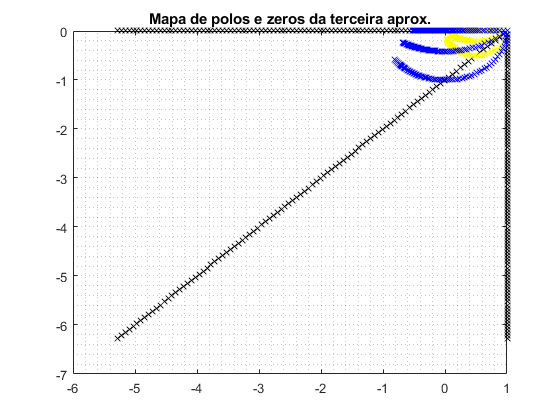

plot(polos2,'yX')
title('Mapa de polos e zeros da segunda aprox.')

plot(polos3,'bX')
title('Mapa de polos e zeros da terceira aprox.')

**Resposta ao degrau**

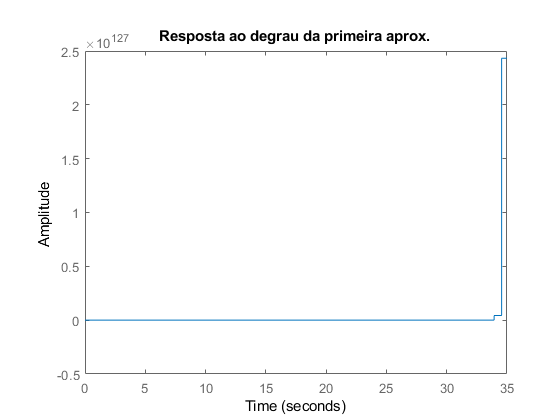

figure()
step(Gz1)
title('Resposta ao degrau da primeira aprox.')

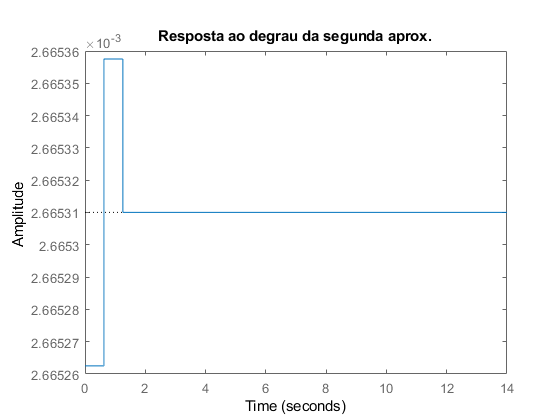

% Como previsto, esta é uma aproximação instável.

figure()
step(Gz2)
title('Resposta ao degrau da segunda aprox.')

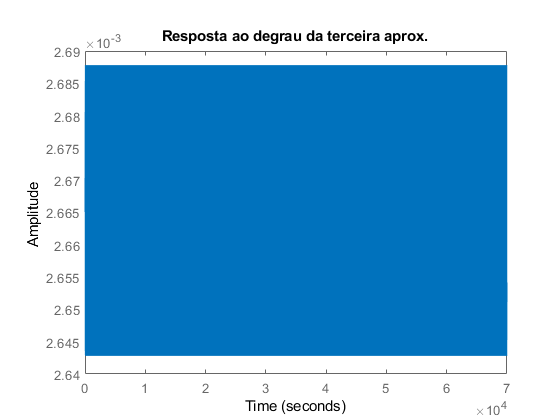

% Como previsto, esta é uma aproximação é estável depois de aprox. 1,5 segundos.

figure()
step(Gz3)
title('Resposta ao degrau da terceira aprox.')

% Esta aproximação é oscilatória, com amplitude de aprox. 2,687 *10^(-3)Vp.

**Eq. de diferenças:**

%Simplificando as funções de transferência
num1=num1/den1(1);
den1 = den1/den1(1);
num2=num2/den2(1);
den2 = den2/den2(1);
num3=num3/den3(1)

num3 =     0.0027    0.0053    0.0027


den3 = den3/den3(1)

den3 =     1.0000    1.9997    1.0000



Gz1 = tf(num1,den1,T)

Gz1 =
 
         149.5
  --------------------
  z^2 - 2 z + 5.611e04
 
Sample time: 0.62832 seconds
Discrete-time transfer function.



Gz2 = tf(num2,den2,T)

Gz2 =
 
          0.002665 z^2
  -----------------------------
  z^2 - 3.565e-05 z + 1.782e-05
 
Sample time: 0.62832 seconds
Discrete-time transfer function.



Gz3 = tf(num3,den3,T)

Gz3 =
 
  0.002665 z^2 + 0.00533 z + 0.002665
  -----------------------------------
             z^2 + 2 z + 1
 
Sample time: 0.62832 seconds
Discrete-time transfer function.




$$G_z1 = \frac{149.5}{z^2-2z+5.611*10^4}$$



$$G_z2 = \frac{0.002665z^2}{z^2-3.565*10^{-5}z+1.782*10^{-5}}$$



$$G_z3 = \frac{0.002665z^2+0.00533z+0.002665}{z^2+2z+1}$$


Primeira aprox.


$$ \frac{Y_1(z)}{U_1(z)}=\frac{149.5z^{-2}}{1-2z^{-1}+5.611*10^4z^{-2}}$$



$$Y_1*(1-2z^{-1}+5.611*10^4z^{-2}) = U_1*(149.5z^{-2})$$



$$Y_1[K]-2Y_1[K-1]+5.611*10^4Y_1[K-2]=149.5
^{-10}U_1[K-2]$$


Segunda aprox.


$$\frac{Y_2(z)}{U_2(z)}=\frac{0.002665}{1-3.565*10^{-5}z^{-1}+1.782*10^{-5}z^{-2}}$$



$$Y_2*(1-3.565*10^{-5}z^{-1}+1.782*10^{-5}z^{-2}) = U_2*0.002665$$



$$Y_2[K]-3.565*10^{-5}Y_2[K-1]+1.782*10^{-5}Y_2[K-2]=0.002665U_2[K]$$


Terceira aprox.


$$\frac{Y_3(z)}{U_3(z)} = \frac{0.002665+0.00533z^{-1}+0.002665z^{-2}}{1+2z^{-1}+z^{-2}}$$



$$Y_3*(1+2z^{-1}+z^{-2})=U_3*(0.002665+0.00533z^{-1}+0.002665z^{-2})$$



$$Y_3[K]+2Y_3[K-1]+Y_3[K-2] = 0.002665U_3[K]+0.00533U_3[K-1]+0.002665U_3[K-2]$$


**Conclusão Geral pelo Simulink**

Como visto em aula, o sinal discreto deu como esperado: maneira digital, em "quadrados", com aproximação para cada momento do período (T). O valor pela equação das diferenças deu contínuo, mas seguindo a linha dada pelo discreto, até que razoavelmente bem aproximada.

As aproximações 2 e 3 estão dando valores iguais no simulink.

A aprox. 1 sempre foi a pior das três, já que esta sempre está instável, se distanceando do valor que queremos.

No simulink, algumas das repostas aos sinais estavam dando valores estraanhos, não esperados (aprox. 2 e aprox. 3 são iguais). Isto provavelmente aonteceu por causa de algum erro teórico, ou por uso errado da ferramenta do simulink.